% A one-way ANOVA showed a highly significant effect of weekday on 
% GroupCount (F(6,14)=30.93, p<10⁻⁶), indicating substantial 
% differences in mean counts across weekdays, with weekday 
% explaining approximately 93% of the total variance.
%
% Once weekends are excluded, weekday activity levels are statistically
% indistinguishable; any apparent differences between Sunday-Thursday are
% likely due to random fluctuation rather than a systematic weekday effect.

anovaTest = ANOVATest('temp\processed_issues.csv');

        2007

        2022



tests = anovaTest.anovaTestForIssuesCountPerDay(3);

        2019



All Days after2019


      Source          SS         df           MS               F              Prob>F     
    __________    __________    ____    ______________    ____________    _______________

    {'Groups'}         62086       6    {[1.0348e+04]}    {[222.1313]}    {[1.5388e-195]}
    {'Error' }         60931    1308    {[   46.5836]}    {0×0 double}    {0×0 double   }
    {'Total' }    1.2302e+05    1314    {0×0 double  }    {0×0 double}    {0×0 double   }



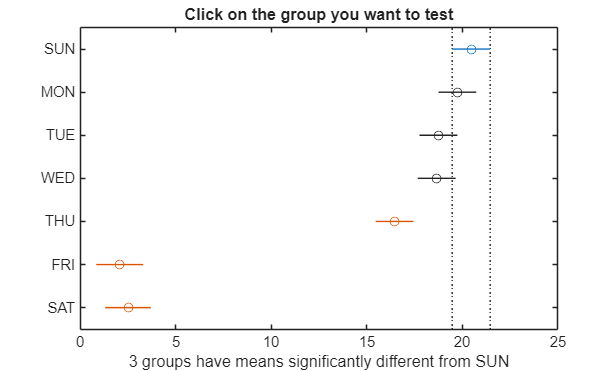

Middle of the Week


      Source       SS       df          MS              F              Prob>F    
    __________    _____    ____    ____________    ____________    ______________

    {'Groups'}     1898       4    {[474.5040]}    {[  8.1840]}    {[1.6946e-06]}
    {'Error' }    59719    1030    {[ 57.9796]}    {0×0 double}    {0×0 double  }
    {'Total' }    61617    1034    {0×0 double}    {0×0 double}    {0×0 double  }



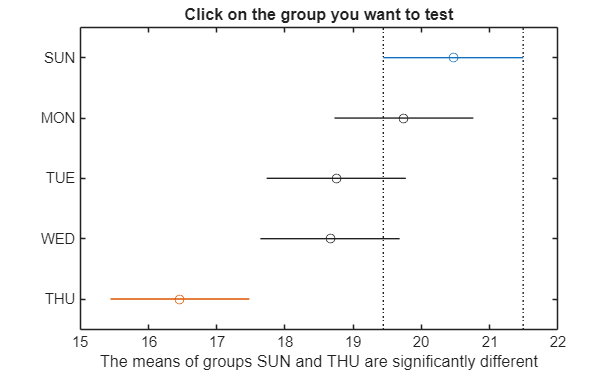

Quarter of the Year


      Source          SS         df          MS              F             Prob>F   
    __________    __________    ____    ____________    ____________    ____________

    {'Groups'}        1085.8       3    {[361.9474]}    {[  3.8916]}    {[  0.0088]}
    {'Error' }    1.2193e+05    1311    {[ 93.0066]}    {0×0 double}    {0×0 double}
    {'Total' }    1.2302e+05    1314    {0×0 double}    {0×0 double}    {0×0 double}



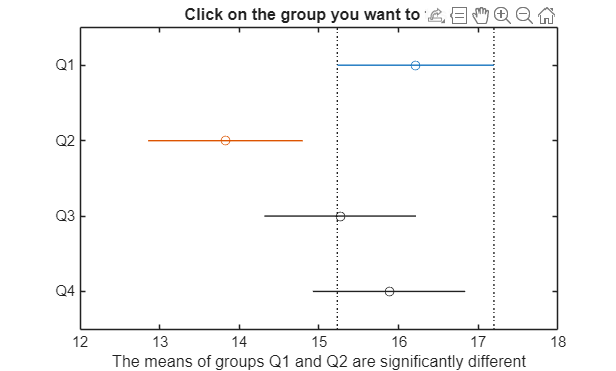

for i = 1:length(tests)
    figure
   t = tests{i};
   disp(t{1});
   table = cell2table(t{3}(2:end,:), 'VariableNames',t{3}(1,:));
   disp(table)
   multcompare(t{4});
   disp("====================================================================")
end

disp('Two-way ANOVA test')

Two-way ANOVA test


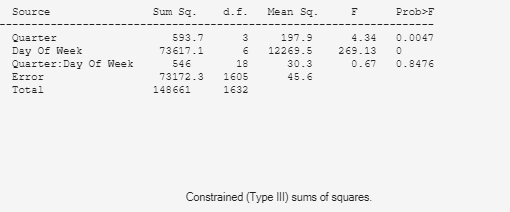

[T, p, tbl, stats] = anovaTest.anova2TestForIssuesCountPerQuarterAndDay(4);

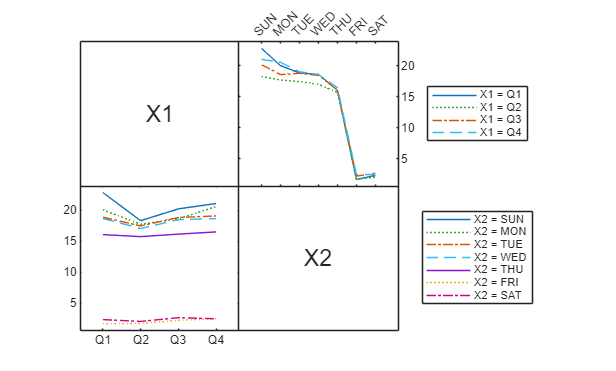

interactionplot(T.GroupCount, {T.quarter, T.day_of_week});

% A two-way ANOVA revealed a strong main effect of day of week on GroupCount
% (F(6,140)=153.66, p<10⁻⁵⁸), a weak but significant main effect of quarter
% (F(3,140)=2.71, p=0.048), and no significant interaction between quarter 
% and day of week (F(18,140)=0.25, p=0.999), indicating that weekday 
% patterns are consistent across quarters.


% | TestName                 | Factor              | df1 | df2 | F     | pValue | Significant | Notes                  |
% | ------------------------ | ------------------- | --- | --- | ----- | ------ | ----------- | ---------------------- |
% | One-way ANOVA (All Days) | DayOfWeek           | 6   | 14  | 30.93 | 2.6e-7 | true        | Weekends dominate      |
% | One-way ANOVA (Weekdays) | DayOfWeek           | 4   | 10  | 0.51  | 0.73   | false       | No weekday differences |
% | One-way ANOVA            | Quarter             | 3   | 8   | 0.72  | 0.57   | false       | No seasonal effect     |
% | Two-way ANOVA            | Quarter × DayOfWeek | 18  | 140 | 0.25  | 0.999  | false       | No interaction         |
